# Multivariate scattered interpolation

## Halton dataset

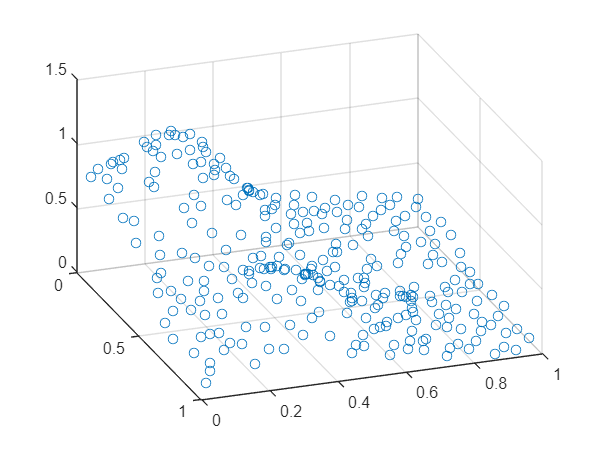

d = 2;                                              % d = space dimension
N = (2^4+1)^2;                                      % N = number of scattered points in R^d

% Generate quasi - random Halton set (see MATLAB Doc for Skip and Leap properties )
p = haltonset (d,'Skip' ,1e3 ,'Leap' ,1e2 );        % define quasi - random object in d- dim
p = p.scramble ('RR2');                             % use scramble method ( reverse - radix )
X = p.net (N);                                      % use net method to generate N points in R^d
F = franke(X(:,1), X(:,2));                                      % compute Franke 's test function

scatter3(X(:,1) ,X(:,2) ,F)
view ([70 35])

## RBF interpolator

dist_name = 'Euclidean';                         % choose a distance (>> doc pdist)
phi = @(r) r .^3;                                % choose an RBF

D = squareform(pdist(X, dist_name));             % 1) compute pairwise distances NxN
A = phi(D);                                      % 2) apply RBF to distances
lambda = A\F                                     % 3) solve linear system A* lambda = F

lambda =    -1.9865
   -0.6718
   -7.0520
    3.0418
  -22.9700
   -0.9012
  -10.3285
   -3.2625
   -2.4465
   -3.2667


## Visualization of RBF interpolator

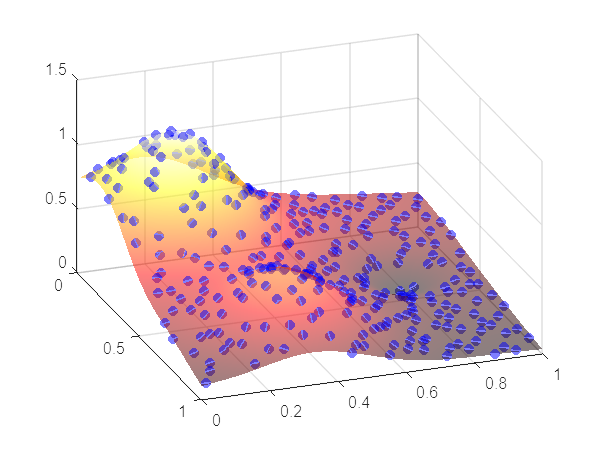

n = 30; % mesh size
gridx = linspace (0 ,1 ,n);  
gridy = linspace (0 ,1 ,n);  
[xe ,ye] = meshgrid(gridx, gridy);              % d uniform meshes (nxn)
eX = [xe(:), ye(:)];                            % stretch into (n^2) x d
eDist = pdist2(eX, X, dist_name);               % pairwise distances to get (n^2) x N
eA = phi(eDist);                                % apply RBF
f_interp = eA* lambda ;                         % multiply by lambda (Nx1) to get (n^2) x 1
f_interp_mat = reshape(f_interp,n,n);           % reshape into nxn

figure
scatter3(X(:,1), X(:,2),F, "b", "filled")
hold on
surf (xe,ye,f_interp_mat)
view ([70 35])
shading interp, colormap hot , alpha (0.5)